
freq = 50;

% Define the file name
crane_file = 'crane_poly_abrupt_06_90.csv';
input_data_pos = csvread("input_poly_position_abrupt_06_90.csv");
input_data_vel = csvread("input_poly_velocity_abrupt_06_90.csv");


% Read the CSV file
data_full = csvread(crane_file,1); % Skip the first 6000 rows
x_position_full = data_full(:, 4);
last_zero_index = find(x_position_full <0.009, 1, 'last');
data = data_full(last_zero_index+10:end,:);
% Extract time (1st column) and x position (4th column)
time =  data(:,1) - data(1,1);
x_position = data(:, 4);
x_velocity = data(:,5);
angle = smoothdata(data(:, 15));
y_position = data(:,6);
first_zero_index = find(x_position <0.01, 1, 'first');
time_shift = time(first_zero_index);
[~,collision_index] = max(x_position);


input_time = 1:length(input_data_pos);
input_position = input_data_pos(1,:)

input_position =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0005    0.0006    0.0007    0.0009    0.0011    0.0013    0.0015    0.0017    0.0020    0.0023    0.0026    0.0030    0.0034    0.0039    0.0044    0.0049    0.0055    0.0061    0.0068    0.0075    0.0083    0.0091    0.0100    0.0110    0.0120    0.0131    0.0142    0.0154    0.0167    0.0181    0.0195    0.0210


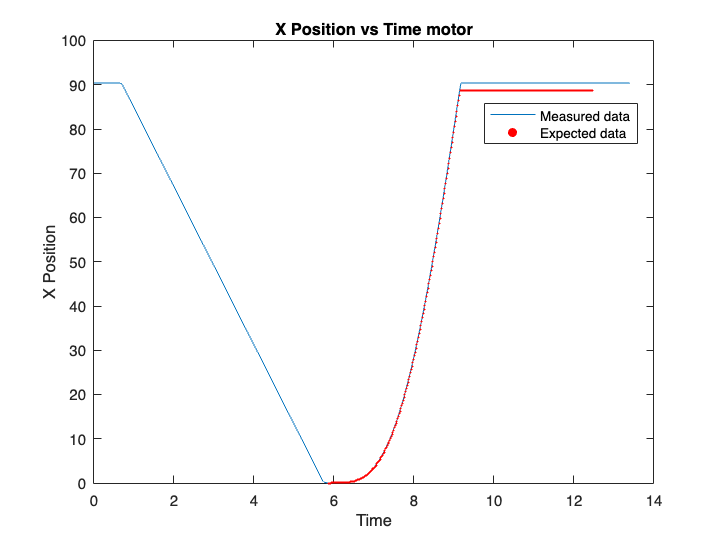


input_velocity = input_data_vel(1,:);


figure;
plot(time, x_position);
xlabel('Time');
ylabel('X Position');
hold on 
scatter(input_time/freq + time_shift, input_position*100, 2, 'r', 'filled');
hold off
title('X Position vs Time motor');
legend('Measured data', 'Expected data', 'Location', 'best');

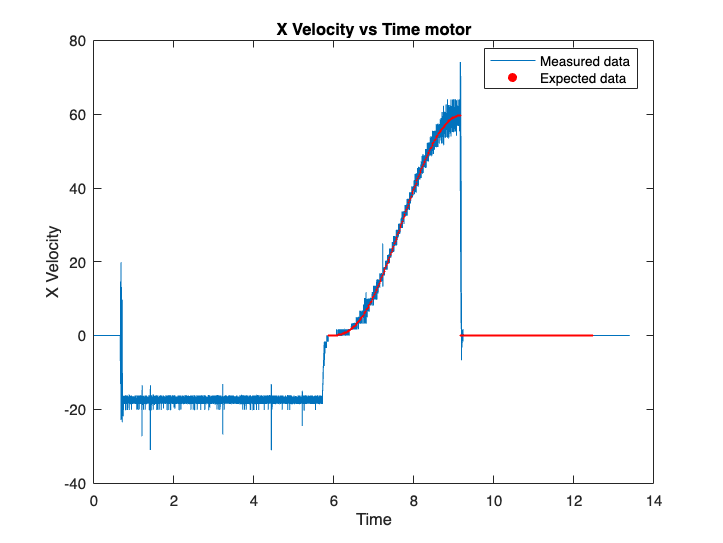



figure;
plot(time, x_velocity);
xlabel('Time');
ylabel('X Velocity');
hold on 
scatter(input_time/freq + time_shift, input_velocity*100, 2, 'r', 'filled');
hold off
title('X Velocity vs Time motor');
legend('Measured data', 'Expected data', 'Location', 'best');

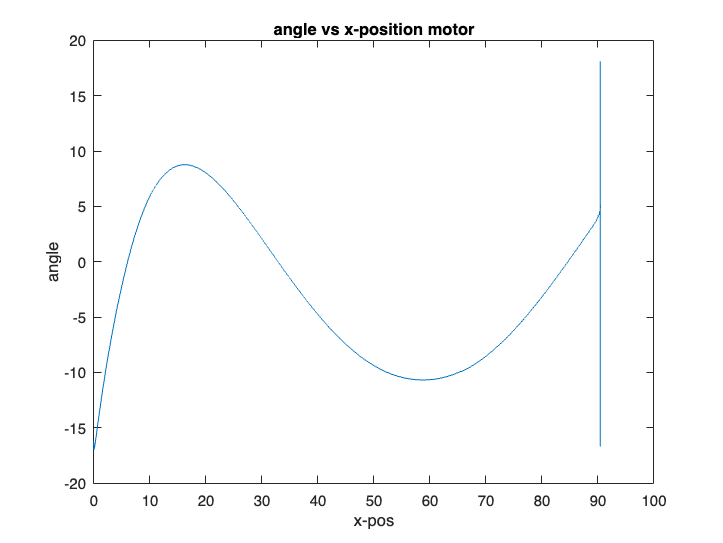




figure
plot(x_position(first_zero_index:end), angle(first_zero_index:end));
xlabel('x-pos');
ylabel('angle');
title('angle vs x-position motor');


figure
plot(time, (angle));
xlabel('time (s)');
ylabel('angle (deg)');
title('angel vs time');
hold on 
xline(time(collision_index))
start_angle = min(angle(1:collision_index-1))

start_angle = -16.9877

new_angle = max(angle(collision_index:end))

new_angle = 18.1249

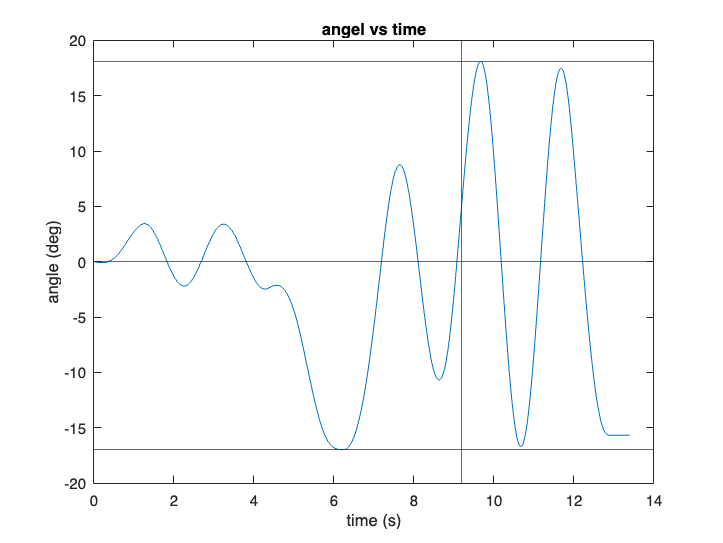

yline(0)
yline(start_angle)
yline(new_angle)
hold off

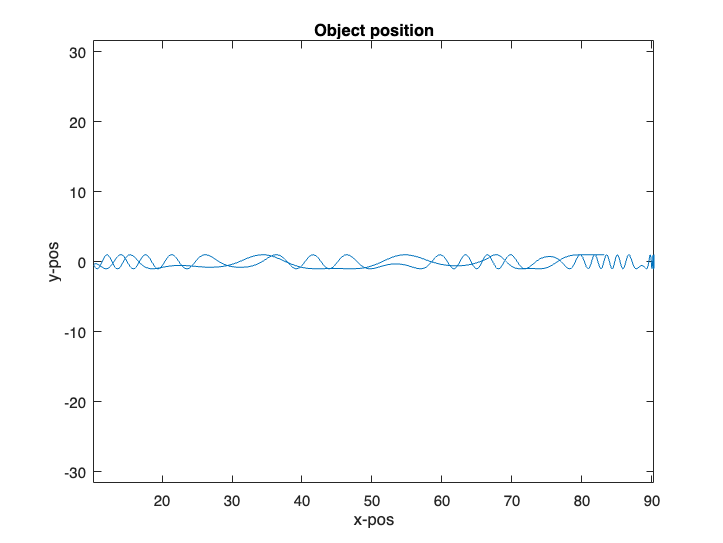



figure
plot(smoothdata(x_position +sin(angle)), cos(angle));
xlabel('x-pos');
ylabel('y-pos');
title('Object position');
axis equal